# Anwenderhandbuch Clustertool

## Kurzbeschreibung des Aufbaus des Clustertools

Dieses Tool enthält verschiedene Methoden um beliebige Objekte zu clustern und die Eigenschaften der Objekte eines Clusters zu visualisieren. Zusätzliche Werkzeuge zur Analyse einer Clusterung sidn ebenfalls implementiert.

Die Motivation der Implementierung ist die Clusterung von Ganglinien der Verkehrsstärke. Dazu werden standardmäßig Kalenderdaten als Eigenschaften berücksichtigt. Ebenso ist der *GEH *als Abstandsmaß verfügbar.

Mit der Funktion [Daten_Importieren.m](matlab:open('Daten_Importieren.m")) werden die Datensätze für die Clusterung importiert importiert und formatiert (falls das Originalformat unterstützt wird). Details dazu s. hier.

Falls der Import erfolgreich abgeschlossen wurde, kann ein Objekt der [Klasse class_Clusterung](matlab: open('class_Clusterung.mat')) erzeugt werden. Diese Klasse ist das Herzstück des Tools & enthält Methoden zur Clusterung, der Verwaltung sowie der Visualisierung einer Clusterung und ihrer Eigenschaften. Ein Objekt der Klasse enthält als Attribut eine Instanz der [Klasse class_Kalender](matlab: open('class_Kalender')). Diese ermöglicht Aussagen zu Tagtypen, Ferien, Jahreszeiten etc.

Nach erfolgreicher Initialisierung des Clusterungobjektes kann die eigentliche Clusterung stattfinden (*obj.Clustern()*). Dazu werden je nach Parameter Funktionen aus der Matlabbibliotek aufgerufen.

### Schnellanleitung

- GUI starten (*start.m *oder* MatNetClusterung.m ausführen)* 

- Daten einlesen -> Button "Clusterdata Datei öffnen"

- Einstellungen vornehmen (Clustermethode, Distanzfunktion, Kalenderdaten, ...)

- Clusterung anlegen -> Button "Neue Clusterung anlegen". Die eingelesenen Daten und die Einstellungen werden gespeichert und können in dieser angelegten Clusterung nicht mehr verändert werden.

- Clusterung starten -> Button "...starten"

## Grafische Benutzeroberfläche (GUI)

Die Benutzerfläche ermöglicht einen Zugriff auf die gebräuchlichsten Parameter und Werkzeuge. Sie ist in 6 Bereiche (A-F) unterteilt:

- A:    Allgemeine Einstellungen/Aktionen

- B:    Einstellungen & Übersicht der Datenauswahl

- C:    Einstellungen & Übersicht der Kalendereigenschaften

- D:    Auswahl & Übersicht der Clusterparameter

- E:    Auflistung einzelner Clusterungen und ihrer Parameter

- F:    Visualisierung der aktiven Clusterung

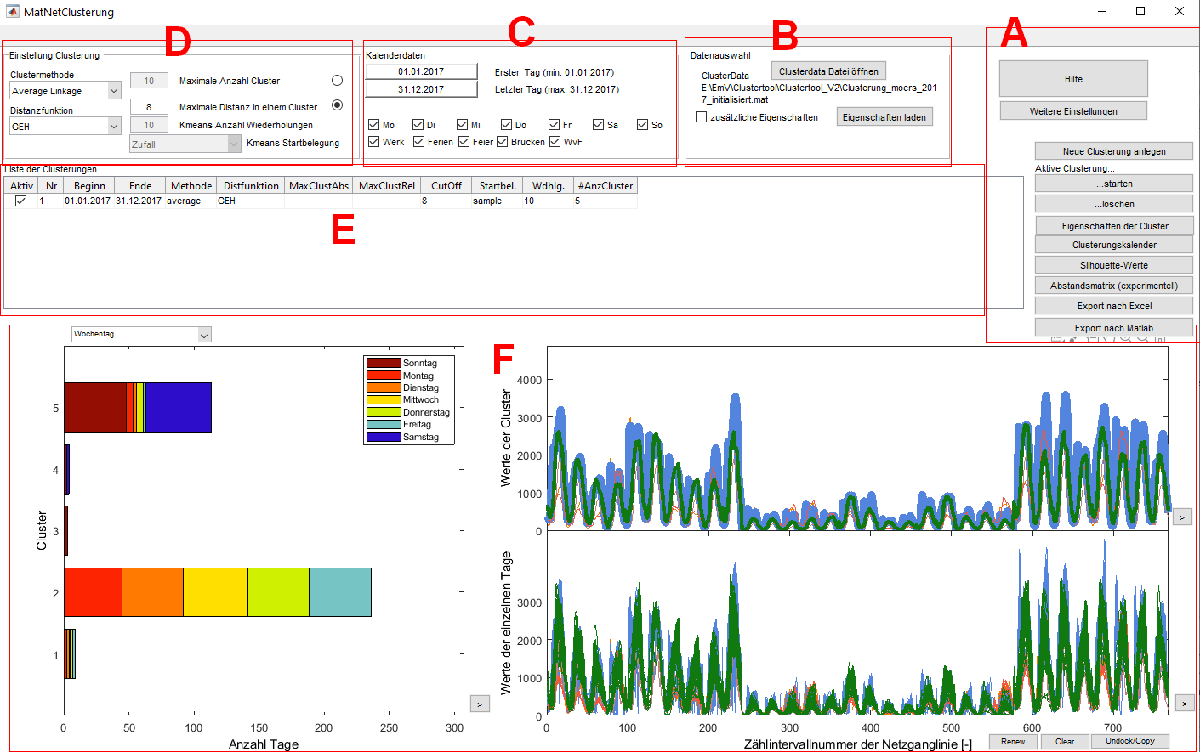

### Allgemeine Einstellungen/Aktionen

Der Bereich A enthält  11 Buttons 

allgemeine Aktionen:

- Hilfe: Öffnet eine Version dieses Dokumentes

- Weitere Einstellungen

- Neue Clusterung anlegen

Aktionen, die sich auf das aktive Clusterobjekt beziehen:

- ... starten

- ... löschen

- Eigenschaften der Cluster

- Clusterungskalender

- Silhouette-Werte

- Abstandsmatrix

- Export nach Excel

- Export nach Matlab

Falls Aktionen nicht durchgeführt werden, sind die entsprechenden Buttons ausgegraut. Nachfolgend werden einige Aktionen erläutert

#### Weitere Einstellungen

Es öffnet sich ein Fenster mit Einstellungen. Es kann ausgewählt werden, ob das Protokoll-Fenster angezeigt werden soll und / oder ob der Vorgang in eine Protokolldaten "Protokoll.txt" 				geschrieben werden soll. Es kann auch eingestellt werden, welche Eigenschaften verwendet werden sollen und von welchem Bundesland die Feiertage und Schulferien bestimmt werden sollen. Alle getätigten Änderungen werden sofort gespeichert. Nach der Einstellung kann das Fenster über das "x" geschlossen werden.

Folgende Skripte werden ausgeführt:

- Weitere_Einstellungen.m

#### Neue Clusterung anlegen

Wenn dieser Button gedrückt wird, werden die oben durchgeführten Einstellungen (Clustermethode, Distanzfunktion, Kalenderdaten, und Datenauswahl) gespeichert. Es wird ein Eintrag in der Tabelle "Liste der Clusterungen" erzeugt. 

Folgende Skripte werden ausgeführt:

- Datei_Importieren.m

- Eigenschaften_Importieren.m

#### ... starten

Die aktive Clusterung (in der Tabelle "Liste der Clusterungen" werden die Clusterungen aktiviert) wird gestartet. Es muss eine Clusterung angelegt sein.Gibt es keine aktive Clusterung, passiert nichts. Die Ausführung kann je nach Datenmenge einige Zeit in Anspruch nehmen. Nach Abschluss der Clusterung wird das Ergebnis in den unteren Schaubildern visuell dargestellt.

Folgende Skripte/Methoden werden ausgeführt:

- TODO

#### ... löschen

Die aktive Clusterung wird gelöscht.

Folgende Skripte/Methoden werden ausgeführt:

- TODO

#### Eigenschaften der Cluster

Zeigt eine Tabelle mit den Eigenschaftswerten der entstandenen Cluster. Der Eigenschaftswert liegt zwischen 0 und 1:

- 0: in diesem Cluster ist kein Tag mit dieser Eigenschaft enthalten

- 1: alle Tage in diesem Cluster haben diese Eigenschaft

- >0 und <0 => der Anteil der Tage mit dieser Eigenschaft

Folgende Skripte/Methoden werden ausgeführt:

- TODO

#### Clusterungskalender

Zeigt den Kalender der Clusterung. Die einzelnen Tage sind entsprechend der Cluster farblich markiert (gleiche Farben wie bei den Schaubildern "mittlerer Clusterganglinien" und "Tagesganglinien"). Durch einen Klick auf die Buttons im unteren Bereich werden die Tage der Cluster fett markiert. Werden einzelne Tage angeklickt wird der entprechende Tag markiert. Mithilfe des Zoom (Lupe im Menü oben linke), können verschieden Eigenschaften des Tages angezeigt werden:

- TagTypNr:			ist die Zuordnung zum Cluster (TagTypNr: 0 sind Tage, welche ausgefiltert wurden == nicht in der Clusterung enthalten sind).

- Clustergröße:		Anzahl der Tage in diesem Cluster

- Abstand zum Cl:	Abstand zwischen dem einzelnen Tag und des Clusters, welchem der Tag zugeordnet ist in der Einheit entsprechend des Distanzmaßes.

- AvgQ:					mittlerer Wert des Tages

- AvgQCluster:		mittlerer Wert des Clusters, welchem der Tag zugeordnet ist

- weitere Eigenschaften des Tages und dahinter die Eigenschaften des Clusters (C:)

Folgende Skripte/Methoden werden ausgeführt:

- TODO

#### Silhouette-Werte

Zeigt die Silhouette Werte der Clusterung. TODO

#### Abstandsmatrix

Zeit die Abstände zwischen den einzelnen Tagen.	Im oberen Schaubild sind die Tage nach dem Datum sortiert. Im unteren Schaubild sind die Tage nach ihrer Cluster - Zugehörigkeit sortiert.

#### Export nach Excel

Die Ergebnisse der Clusterung werden in eine Excel-Datei (*.xlsx oder *.xls) geschrieben.	Es werden 4 Tabellenblätter erzeugt:

- ClusterLinien:                          darin enthalten sind die Verläufe der entstandenen Cluster

- ClusterData:			        hier sind nochmals die Inputdaten (Tagesganglinien) jedoch ist in der zweiten Spalte die Zuordnung zum Cluster enthalten.

- Eigenschaften:				die Eigenschaften der Cluster wie bei "- 4 - Eigenschaften der Cluster"

- Eigenschaften_ClusterData:	die Eigenschaften der Inputdaten (Tagesganglinien)

Folgende Skripte/Methoden werden ausgeführt:

- TODO

#### Export nach Matlab

Die Ergebnisse der Clusterung werden in eine *.mat Datei geschrieben. Die in der Datei gespeicherte Variable "Clusterung" ist vom Typ "class_Clusterung". In dieser Variable sind alle Daten enthalten (Einstellungen, Inputdaten, Einstellungen, ClusterLinien, uvm.). Mehr Infos zum Aufbau der Klasse findet man in der Datei "class_Clusterung.m". Eine Exportierte Clusterung nach Matlab kann wieder mit "Clusterdata Datei öffnen" geladen werden. Es kann dabei die gesamte Clsuterung geladen werden oder nur die Inputdaten. Dieses Feature kann z.B. auch dann verwendet werden, wenn das Laden von größeren Datenmengen von Excel sehr viel Zeit in Anspruch nimmt. Das Laden von Matlab-Daten ist deutlich schneller. Siehe dazu auch "Clusterdata Datei öffnen " bei Datenauswahl.

Folgende Skripte/Methoden werden ausgeführt:

- TODO

### Einstellungen & Übersicht der Datenauswahl

Es gibt 2 Buttons in Feld "Datenauswahl":

- 	Clusterdata Datei öffnen

- 	Eigenschaften laden (optional, !!! Die Eigenschaften haben KEINEN Einfluss auf das Clusterergebnis !!!)

#### Clusterdata Datei öffnen

"Clusterdata Datei öffnen" muss gewählt werden. Es öffnet sich ein Dialog mit dem eine Datei ausgewählt werden soll, in der die zu clusternde Objekte enthalten sind. Es kann wahlweise eine *.mat (Matlab) Datei oder eine *.xlsx (Excel) Datei verwendet werden. Dabei wird ein bestimmtes Datenformat gefodert:

Die erste Spalte muss das Datum enthalten. Es werden folgenden Datumsformate unterstützt:

- Matlab-Serial-Zeit , z.B. 735600 für 01.01.2014

- Unix-Zeit, z.B. 1388530800 für 01.01.2014

-  Excel-Serial-Zeit, z.B. 41640 für 01.01.2014

- dd.mm.yyyy, z.B. 01.01.2014

- dd.mm.yyyy HH:MM, z.B. 01.01.2014 00:00

- dd.mm.yyyy HH:MM:SS, z.B. 01.01.2014 00:00:00

- dd.mm.yy, z.B. 01.01.14

- dd.mm.yy HH:MM, z.B. 01.01.14 00:00

- dd.mm.yy HH:MM:SS, z.B. 01.01.14 00:00:00

Für die Verkehrsstärken gibt es 2 Möglichkeiten:

#### Eingabe als Netzgangline (damit sind mehrere Detektoren möglich)

Pro Tag darf nur eine Zeile verwendet werden. Alle Verkehrsstärken eines Tages müssen in verschiedenen Spalten in einer Zeile stehen. Die weiteren Spalten können beliebige numerische Werte enthalten. Wichtig ist nur, dass innerhalb einer Spalte die Werte gleicher Zeitbezüge innerhalb des Tages stehen. Bei der Berechnung der Distanz werden die gleichen Spalten der unterschiedlichen Tage verwendet, d.h. die Verkehrsstärken gleicher Zeitbezüge werden miteinander vergleichen. Die Anzahl der Spalten ist beliebig.

Beispiel: 

01.01.2014	1500	2000	3000 (1. Spalte: Zeit, 2. Spalte Verkehrsstärke an diesem Tag um 01:00 Uhr, 3. Spalte um 02:00 Uhr, 4. Spalte um 03:00 Uhr)

02.01.2014	1700	1800	2400 (1. Spalte: Zeit, 2. Spalte Verkehrsstärke an diesem Tag um 01:00 Uhr, 3. Spalte um 02:00 Uhr, 4. Spalte um 03:00 Uhr)

####  Eingabe in Zeilen (damit kann nur ein Detektor geclustert werden)

 Hierbei werden nur 2 Spalten berücksichtigt: 1. Spalte: Zeit, 2. Spalte: Verkehrsstärken zur Zeit.

#### Einlesen der Daten von Excel

Wenn eine Excel Datei ausgewählt wird, welche mehrere Tabellenblätter (Sheets) mit Daten enthält, öffnet sich ein kleines Fenster mit der Auflistung der Tabellenblätter (Sheets) in dieser Excel Datei. Es muss nun ausgewählt werden, in welchem Tabellenblatt die Daten (UND NICHTS ANDERES) enthalten sind.

!!! Die Daten müssen in der ersten Zeile beginnen. Die erste Spalte A muss das Datum enthalten !!!

#### Einlesen der Daten von Matlab

Die Daten können auch von einer Matlab Datei (*.mat) geselen werden. Enthält die Matlab Datei (*.mat) mehrere Vatriablen, öffnet sich eine Fenster und es soll die zu verwendete Variable ausgewählt werden. Ansonsten gleten die gleichen Anforderungen wie bei der Excel-Datei. Es können auch frühere Clusterungen geladen werden. Durchgeführte Clusterungen lassen sich mit dem todo Button "Export nach Matlab" speichern. Die Dabei werden sowohl die Inputdaten als auch die Cluster gespeichert.

Beim Laden einer Outputdatei gibt es zwei Optionen:

- Es sollen nur die Inputdaten der Clusterung geladen werden. Hierbei werden nur die einzelnen Tagesganglinien, welche in der Clusterung verwendet wurden geladen.Das Auslesen der Daten aus Excel kann unter Umständen viel Zeit in Anspruch nehmen. Wird eine Clusterung mir diesen Daten exportiert, können diese Daten	später über das Laden der Clusterung deutlich schneller eingelesen werden.

- Es soll die vollständige Clusterung geladen weden. Hierbei wird eine Clusterung angelegt (zu sehen in der Tabelle: Lister der Clusterungen).	Es werden alle Daten und Clusterergebnisse geladen und die geladene Clusterung wird direkt visuell dargestellt.

#### Eigenschaften laden (optional)

Es können zusätzliche Eigenschaften zu den einzelnen Tagen geladen werden. **Die Eigenschaften haben KEINEN Einfluss auf das Clusterergebnis. Die Kalendereigenschaften ermöglichen jedoch eine Filterung der Daten (s. **Einstellungen & Übersicht der Kalendereigenschaften). Die Betrachtung von Eigenschaften der Elemente eines Clusterns ermöglicht es, Zusammenhänge abzuleiten. Pro Spalte wird eine Eigenschaft für jede Uhrzeit/jedes Datum eingetragen.

Die Daten müssen folgendermaßen aufgebaut sein:

- 1. Spalte: Datum (es werden die gleichen Formate wie bei " A.) Clusterdata Datei öffnen" unterstützt).

- 2:n. Spalte :beliebige Eigenschaften.

Diese Eigenschaften müssen nicht numerisch sein (es ist sogar besser wenn ein Text drin steht). Weiter können den einzelnen Tagen beliebige Eigenschaften hinzugefügt werden (z.B. Baustelle, Unfall oder auch Fußballspiel, Großveranstaltung). Die Bezeichnungen der Eigenschaften muss so verändert werden, damit Matlab ein Feld für eine Struct machen kann: D.h. die Zeichen ä,ö,ü, ß und Leerzeichen sind nicht erlaubt und werden in ae, oe, ue, ss und _ umgewandelt. Zusätzlich gibt es die Option der Eigenschaft eine Überschrift zu geben. In diesem Fall beginnt das Datum erst in der zweiten Zeile. Die Eigenschaften können später visuell oder als Tabelle für die einzelnen Cluster angezeigt werden.

% Beispiel Eigenschaften
load("Data\Eigenschaft_Wetter.mat");

### Einstellungen & Übersicht der Kalendereigenschaften

In diesem Feld kann die Zeitraum gefiltert werden, der geclustert werden soll. Zum einen können über verschiedene Checkboxen Wochentage oder weitere besondere Tage (Ferien, Feiertage, ...) ausgefiltert werden. Das wird gemacht indem die entsprechende Checkbox deaktiviert wird. Wenn Daten eingelesen wurden (siehe "Clusterdata Datei öffnen"), entstehen zwei Felder, die den Start und Endzeitpunkt der Clusterung bestimmten. Durch Klick auf die Felder kann für die Clusterung ein Zeitintervall innerhalb des Start- und Endzeitpunktes festgelegt werden. 

### Auswahl & Übersicht der Clusterparameter

Die entscheidenden Parameter einer Clusterung sind die Wahl der Distanzfunktion und der Clustermethode. Folgende Distanzfunktionen können in der GUI gewählt werden:

- GEH: empfohlenes Abstandsmaß für Verkehrsstärken [Kfz/h]. Der GEH-Wert berücksichtigt sowohl absolute als auch relative Differenzen $GEH = \sqrt{\frac{2 \left(m-c \right) ^2}{m + c}}$	

- Euklidische Distanz

Weiter stehen folgende Clusterfunktionen zur Verfügung:

- k-Means: das entspricht einer Unterteilung der Daten in *k *Cluster, so dass die Summe der quadrierten Abweichungen von den Schwerpunkten der Cluster minimiert wird. Die Anzahl *k* der Cluster wird vorgegeben

Hierarchische Clustermethoden:

Bei den hierarchischen Clustermethoden werden solange Cluster aggregiert, bis eine maximale Distanz innerhalb des Clusters erreicht wird. Die Methoden unterscheiden sich in den Aggregationsfunktionen zur Berechnung der Distanzen

- Single Linkage (="nearest neighbor"): Hier wird die minimale Distanz berücksichtigt

- Complete Linkage: Hier wird die maximale Distanz berücksichtigt

- Average Linkage  (wird für Verkehrsstärken empfohlen): Dabei wird der arithmetische Mittelwert gebildet

- Weighted Linkage: Dabei wird der gewichtete Mittelwert gebildet

- Median Linkage: euklidischer Abstand zwischen gewichteten Schwerpunkten

- Ward - Verfahren 

In den Funktionen *kmeans *und *linkage *der Matlabbibliothek werden die Verfahren detailliert beschrieben

doc linkage
doc kmeans

Für dieses Tool wurde die Funktion *kmeans* zu *kmeans_adjusted.m* erweitert. Die angepasste Funktion enthält die zusätzliche Distanzfunktion GEH.

Weiter muss eine eingestellt werden, wie detailliert die Clusterung sein soll, d.h. ob sehr grob oder fein geclustert werden soll. Mithilfe der beiden Radiobuttons auf der rechten Seite kann eingestellt werden, ob 

- eine Anzahl an Clustern vorgegeben werden soll; oberer  Button (wird bei Tagesganglinien NICHT empfohlen)

- ein maximales Distanzmaß verwendet werden soll; unterer Button (empfohlen, aber bei kmeans nicht möglich). Die Größenordnung bei der Euklidische Distanz und dem GEH unterscheiden sich stark.

- Kmeans Anzahl Wiederholungen (nur aktiv, wenn KMEANS ausgewählt wurde).	Bei Kmeans wird das Verfahren mehrfach durchgeführt (da die Startbelegung idR zufüllig ist) und am Ende das beste Ergebnis verwendet.

- Kmeans Startbelegung (nur aktiv, wenn KMEANS ausgewählt wurde). Die Einstellung Vorclusterung  (Matlab: cluster) macht eine Vorclusterung mit 10% der Objekte

### Auflistung einzelner Clusterungen und ihrer Parameter

Dieser Bereich enthält eine Übersichtstabelle der existierenden Cluster und ihrer Parameter. Es kann jeweils nur ein Cluster aktiv sein.

### Visualisierung der aktiven Clusterung

Dieser Bereich enthält 3 Diagramme:

- Werte der Cluster (rechts oben)

- Werte der einzelnen Tage ( rechts unten)

- Cluster (links)

In der unteren rechten Ecke des Fensters gibt es noch zwei Buttons "Renew" und "Clear".

- Renew: Zeichnet alle Cluster und die Werte der einzelnen Tage wieder neu.

-  Clear: Löscht die Darstellungen in den rechten beiden Diagrammen.

Neben jedem der 3 Diagramme (rechts unten) ist ein kleiner Button ">". Dieser öffnet das Diagramm in einem separatem Fenster. Dort kann man sich den Inhalt vergrößert anschauen kann und z.B. auch als Matlab-Figure oder Bild (png, jpeg) speichern kann. Der Button "Undock/Copy" (ganz unten rechts im Fenster) bringt die beiden rechten Diagramme zusammen in ein neues Fenster.

#### Werte der Cluster (Position: rechts oben)

Hier sind die resultierende Cluster dargestellt. Der Verlauf ergibt sich aus dem Mittelwert aller Tageswerte, die dem Cluster zugeordnet sind.	Die breite der Linien ist abhängig von der Anzahl der Tage, welche diesem Cluster zugeordnet wurde. Durch den Klick auf eine Linie wird die Clusternummer der Linie gezeigt. Die Clusternummer kann wieder entfernt werden, wenn auf die gezeigte Clusternummer geklickt wird.  

Folgende Skripte/Methoden werden ausgeführt:

- TODO

#### Werte der einzelnen Tage (Position: rechts unten)

Hier werden die Inputdaten (Tagesganglinien) dargestellt. Die Farbe der Linien zeigt die Zugehörigkeit zum Cluster.	Durch den Klick auf eine Linie wird das Datum der Linie gezeigt. Das Datum wird im Format ddd dd.mm.yyyy angezeigt. ddd entspricht der englischen Wochentagsabkürzungen (Sun: Sonntag, Mon: Montag, Tue: Dienstag, Wed: Mittwoch, Thu: Donnerstag, Fri: Freitag, Sat: Samstag). Das Datum kann wieder entfernt werden, wenn auf das gezeigte Datum geklickt wird. 

Folgende Skripte/Methoden werden ausgeführt:

- TODO

#### Cluster (Position: links)

Hier werden die Clustereigenschaften dargestellt.	Über dem Diagramm ist ein Pop-Up Menü mit dem die verschiednen Eigenschaften ausgewählt werden können (Ferien, Wochentag, ...).		Für jedes Cluster wird ein Balken mit den enthaltenen Eigenschaften dargestellt. Mit dem Klick auf einen Balken wird dieser Balken gezeigt. Bei erneutem Klick auf den selben Balken wird dieser wieder ausgeblenden. Damit ist es möglich einzelne Cluster direkt miteinander zu vergleichen.

Tipp: Mit "Undock/Copy" und ">" wird nur die entsprechende Auswahl (rechte Diagramme) ins neue Fenster exportiert.

Folgende Skripte/Methoden werden ausgeführt:

- TODO

## Datenimport

file = 'E:\EmV\Clustertool\Input Clusterung\Moers_2017_.mat';

[Daten, Dateiendung] = Datei_Oeffnen(file);

## Initialisieren einer Clusterung 

param=struct( ...
             'Methode',                 'average' ...   % Methode={'Kmeans', 'single', 'complete', 'average', 'weighted', 'median', 'ward'}
            ,'Distanzfunktion',         'GEH' ...       % Distanzfunktion={'GEH', 'Euclidean_mit_NaN'}
            ,'ClusterAnzahlAbs',        10 ...          % ClusterAnzahlAbs/ClusterAnzahlRel - legt die Anzahl der Cluster fest, wobei diese auch von der Anzahl Tage der Gruppe der Vorklassifizierung abhängt
            ,'ClusterAnzahlRel',        0.25 ...        %	   es wird der kleinere Wert aus ClusterAnzahlAbs und ClusterAnzahlRel*AnzahlTage gewählt
            ,'CutOff',                  [] ...          % CutOff - Für Methoden~=kmeans steht der Wert CutOff zur Bestimmung der Anzahl cluster zur Verfügung (ist dieser nicht [] haben ClusterAnzahlAbs/ClusterAnzahlRel keine Bedeutung
            ,'Auswahl_Startcluster',    'sample' ...    % Auswahl_Startcluster = {'sample', 'uniform', 'cluster'} - steht nur für Kmeans zur Verfügung und bestimmt die Belegung der Startcluster (siehe Matlab-Doku)
            ,'Replicates',              10 ...          % Replicates = long - steht nur für Kmeans zur Verfügung und bestimmt die Anzahl Iterationen/Wiederholungen der Clusterung um ein globales Minimum zu finden
            ,'Auswahl_Tage',            [] ...          % Auswahl_Tage = eine manuelle Auswahl an Tagen, für die geclustert werden soll (wird im Konstruktor nochmals initialisiert)
            ,'Tage_filtern',            [] ...          % Tage_filtern = zusätzlich zu "Auswahl_Tage", können Tage angegeben werden, die ausgefiltert werden sollen
            ,'flag_2412_und_3112_auch_Feiertage', false ... % Sollen der 24.12. und der 31.12. auch als Feiertage festgelegt werden?
            );

clusterobject = class_Clusterung(Daten, param, [], []);


## Durchführen einer Clusterung

## Aufbau des Tools

In diesem Kapitel werden einzelne Elemente des Clustertools beschrieben.

### Klasse Clusterung

### Klasse Kalender

### Sonstige Skripte

#### Daten_Importieren